# Script02＿状態平均化モデルから伝達関数の導出

Copyright (c) 2022, The MathWorks, Inc.All rights reserved.

本スクリプトではScript01で導出した状態平均化モデルの代数式を元に入力電圧、出力電流、Dutyの3つの入力に対して出力電圧の伝達関数を求める。

**代数演算ツールを使うことで手計算で求めた代数演算の検算が可能であるだけでなく**

**MATLABとSymbolic Math Toolbox、そしてControl System Toolboxを組み合わせて使えば**

**代数式で計算した伝達関数の周波数特性をボード線図で描画させることができるので、**

**立式から周波数特性の確認というところまでを一貫して実施できることを確認する。**

## 1.状態平均化モデルの呼び出し

Script01を実行し、導出した代数式演算結果をワークスペースに展開します

clear variables
load('Parameters/AveragedState-SapaceModel.mat')

## 2. 定常解（静特性式）の導出

いわゆる伝達関数、動特性はある定常解に対して微小変動を注入した際の

各状態の変化量を求める"小信号解析"を行うため、

動特性に対する解析を行うには基準となる定常解式を得る必要がある。

$\frac{\mathrm{d}}{\mathrm{d}t}\mathit{\mathbf{x}}\left(t\right)\;=0$とすることで、静特性、

即ちある入力に対して出力が収束する地点を導出することができる。

今まで、状態をtの関数として$\mathit{\mathbf{x}}\left(t\right)$と表現したが、

定常解は時間の関数ではないある固定の数値としての解を得る。

これらを区別するために、

提示した状態変数の定常解を大文字を用いて$\mathit{\mathbf{X}}=\left\lbrack \begin{array}{c}
I_L \\
V_c 
\end{array}\right\rbrack$、出力を$U=V_{\textrm{in}}$と記述することにする。


$$\begin{array}{l}
0=\mathit{\mathbf{A}}X+{\textrm{BV}}_{\textrm{in}} \cdots \left(2\ldotp 1\right)\\
\textrm{Vo}=\textrm{CX}\cdots \left(2\ldotp 2\right)
\end{array}$$


$\mathit{\mathbf{X}}$導出のために式(2.1)を変形し

$\mathit{\mathbf{X}}=-{\mathit{\mathbf{A}}}^{-1} \textrm{BU}$を計算する代数式演算を行う。

%新規代数シンボルを定義
syms X U Iout Vout Vin Ro Duty t;

U = Vin

$$U = \mathrm{Vin}$$

X = -inv(A)*B*U

$$X = \left(\begin{array}{c} \frac{\mathrm{Duty}\,\mathrm{Vin}}{\mathrm{Ro}}\\ \mathrm{Duty}\,\mathrm{Vin} \end{array}\right)$$

定常解$\mathit{\mathbf{X}}$を上記の通り取得することができた。これを式(4.2)出力方程式に代入すると

Vout = C*X 

$$Vout = \mathrm{Duty}\,\mathrm{Vin}$$

## 3. 定常状態近傍での動特性式の導出

導出した定常解の近傍で小信号解析を行う。

コンバータの出力電圧である${V_{\textrm{out}} =v}_C$に変化をもたらす入力は式(2.11)で定義された通り


$$\mathit{\mathbf{u}}\left(t\right)=V_{\textrm{in}}$$


のだけでなく、時比率$\textrm{Duty}$,負荷抵抗$R_o$も含まれる。

現状の状態空間モデルはこれらの入力がA行列、B行列の内部に定義されてしまっている。

そこで$\textrm{Duty}$,$R_o$で式を偏微分し、

その微分演算結果の１次項のみを採用することで近似した式を、

定常解近傍での線形化式とすることで動特性を導出することを試みる。


$$\begin{array}{l}
\textrm{Duty}\to \textrm{Duty}+\Delta \textrm{Duty}\left(t\right)\\
R_o \to R_o +\Delta R_o \left(t\right)\\
\mathit{\mathbf{x}}\left(t\right)\to \mathit{\mathbf{X}}+\Delta \mathit{\mathbf{X}}\left(t\right)\\
\mathit{\mathbf{u}}\left(t\right)\to \mathit{\mathbf{U}}+\Delta \mathit{\mathbf{U}}\left(t\right)=V_{\textrm{in}} +\Delta V_{\textrm{in}} \left(t\right)\\
v_{\textrm{out}} \left(t\right)\to V_{\textrm{out}} +\Delta V_{\textrm{out}} \left(t\right)
\end{array}$$


の変動を式(4.1),(4.2)に代入する。

各状態空間行列をみると$\mathit{\mathbf{A}}$が$R_o$の関数であり、$B$が$\textrm{Duty}$の関数となっており、

それ以外の行列は$R_o$、$\textrm{Duty}$を含まないため偏微分演算結果が０になる。

それを考慮すると式は下記のとおりとなる。


$$\begin{array}{l}
\frac{d}{\mathrm{d}t}\mathit{\mathbf{X}}+\frac{d}{\mathrm{d}t}\Delta \mathit{\mathbf{X}}\left(t\right)=\left(\mathit{\mathbf{A}}+\frac{\partial }{\partial R_o }A\Delta R_o \right)\left(\mathit{\mathbf{X}}+\Delta \mathit{\mathbf{X}}\left(t\right)\right)+\left(B+\frac{\partial }{\partial \textrm{Duty}}B\Delta \textrm{Duty}\right){\mathit{\mathbf{V}}}_{\textrm{in}} +\Delta \textrm{Vin}\left(t\right)\cdots \left(3\ldotp 1\right)\\
V_o +\Delta V_o \left(t\right)=\mathit{\mathbf{C}}\left(\mathit{\mathbf{X}}+\Delta \mathit{\mathbf{X}}\left(t\right)\right)\cdots \left(3\ldotp 2\right)
\end{array}$$


式(3.2)を計算して


$$\frac{d}{\mathrm{d}t}\textrm{X＋}\frac{d}{\mathrm{d}t}\Delta \mathit{\mathbf{X}}\left(t\right)=\textrm{AX}+\textrm{BVin＋}\frac{\partial }{\partial R_o }A\Delta R_o \left(t\right)\textrm{X＋A}\Delta \mathit{\mathbf{X}}\left(t\right)+\frac{\partial }{\partial R_o }\mathit{\mathbf{A}}\Delta \mathit{\mathbf{X}}\left(t\right)\Delta R_o +\frac{\partial }{\partial \textrm{Duty}}\mathit{\mathbf{B}}\Delta \textrm{Duty}\left(t\right)\textrm{Vin}+\mathit{\mathbf{B}}\Delta \textrm{Vin}\left(t\right)+\frac{\partial }{\partial \textrm{Duty}}B\Delta \textrm{Duty}\Delta \textrm{Vin}\left(t\right)\cdots \left(3\ldotp 3\right)$$


この式の左辺の$\frac{d}{\mathrm{d}t}\mathit{\mathbf{X}}$を計算すると下記の通り０となるので

dLXdt = diff(X,t)

$$dLXdt = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

式$\left(3\ldotp 3\right)$から$\frac{d}{\mathrm{d}t}\mathit{\mathbf{X}}$を削除する。

加えて式$\left(2\ldotp 1\right)$に示す定常解の解析から$0=\textrm{AX}+{\textrm{BV}}_{\textrm{in}}$であるため

式$\left(3\ldotp 3\right)$から$\textrm{AX}+{\textrm{BV}}_{\textrm{in}}$を削除する。


$$\frac{d}{\mathrm{d}t}\Delta \mathit{\mathbf{X}}\left(t\right)=\frac{\partial }{\partial R_o }A\Delta R_o \left(t\right)\textrm{X＋A}\Delta \mathit{\mathbf{X}}\left(t\right)+\frac{\partial }{\partial R_o }A\Delta \mathit{\mathbf{X}}\left(t\right)\Delta R_o +\frac{\partial }{\partial \textrm{Duty}}B\Delta \textrm{Duty}\left(t\right)\textrm{Vin}+B\Delta \textrm{Vin}\left(t\right)+\frac{\partial }{\partial \textrm{Duty}}B\Delta \textrm{Duty}\Delta \textrm{Vin}\left(t\right)\cdots \left(3\ldotp 4\right)$$


微小変動項同士が掛け算されている２次の微小項を０として扱う近似を施すと


$$\frac{d}{\mathrm{d}t}\Delta \mathit{\mathbf{X}}\left(t\right)=\frac{\partial }{\partial R_o }A\Delta R_o \left(t\right)\textrm{X＋A}\Delta \mathit{\mathbf{X}}\left(t\right)+B\Delta \textrm{Vin}\left(t\right)+\frac{\partial }{\partial \textrm{Duty}}B\Delta \textrm{Duty}\left(t\right)\textrm{Vin}\cdots \left(3\ldotp 5\right)$$


式(2.2)の出力方程式の定常解を元に左辺の$\textrm{Vo}$に代入して式を整理すると


$$\Delta V_o \left(t\right)=\mathit{\mathbf{C}}\Delta \mathit{\mathbf{X}}\left(t\right)\cdots \left(3\ldotp 6\right)$$


**式(3.5)(3.6)が降圧コンバータの時間領域における動特性基本式となる。**

## 4.ラプラス変換

式(3.5)をラプラス変換する。

ラプラス変換により$t$の関数は$\mathit{\mathbf{s}}$の関数となり、微分演算子はラプラス演算子$\mathit{\mathbf{s}}$と表現されるため


$$\mathit{\mathbf{s}}\Delta \mathit{\mathbf{X}}\left(s\right)=\mathit{\mathbf{A}}\Delta \mathit{\mathbf{X}}\left(s\right)+\frac{\partial }{\partial R_o }A\Delta R_o \left(s\right)\mathit{\mathbf{X}}+B\Delta \textrm{Vin}\left(s\right)+\frac{\partial }{\partial \textrm{Duty}}\textrm{BVin}\Delta \textrm{Duty}\left(s\right)$$

$$\cdots \left(4\ldotp 1\right)$$


$\mathit{\mathbf{A}}\Delta \mathit{\mathbf{X}}\left(s\right)$を左辺に移行して


$$\mathit{\mathbf{s}}\Delta \mathit{\mathbf{X}}\left(s\right)-\mathit{\mathbf{A}}\Delta \mathit{\mathbf{X}}\left(s\right)=\frac{\partial }{\partial R_o }A\Delta R_o \left(s\right)\mathit{\mathbf{X}}+B\Delta \textrm{Vin}\left(s\right)+\frac{\partial }{\partial \textrm{Duty}}\textrm{BVin}\Delta \textrm{Duty}\left(s\right)$$

$$\cdots \left(4\ldotp 2\right)$$


左辺を$\Delta \mathit{\mathbf{X}}\left(s\right)$とした式にするため両辺を$\left(\textrm{sI}-\mathit{\mathbf{A}}\right)$で割ると


$$\Delta \mathit{\mathbf{X}}\left(s\right)={\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} \left(\frac{\partial }{\partial R_o }A\Delta R_o \left(s\right)\mathit{\mathbf{X}}+B\Delta \textrm{Vin}\left(s\right)+\frac{\partial }{\partial \textrm{Duty}}\textrm{BVin}\Delta \textrm{Duty}\left(s\right)\right)\cdots \left(4\ldotp 3\right)$$


(3.6)の出力方程式についてもラプラス変換を施すと


$$\Delta V_o \left(s\right)=\mathit{\mathbf{C}}\Delta \mathit{\mathbf{X}}\left(s\right)\cdots \left(4\ldotp 6\right)$$


以上によりラプラス変換にが行えた。

ここで、微小変動$\Delta R_o \left(s\right)$、$\Delta \textrm{Vin}\left(s\right)$、$\Delta \textrm{Duty}\left(s\right)$に対する

状態の微小変動量$\Delta \mathit{\mathbf{X}}\left(s\right)$の比が伝達関数として扱える。

例えば$\Delta R_o \left(s\right)$についての$\Delta \mathit{\mathbf{X}}\left(s\right)$の伝達関数を導出する際、他の微小変動$\Delta \textrm{Vin}\left(s\right)$、$\Delta \textrm{Duty}\left(s\right)$については変動が0であり、

$\Delta R_o \left(s\right)$でのみ微小変動が発生する状況を想定すると、条件付きで下記式が求められる。

$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta R_o \left(s\right)}={\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} \left(\frac{\partial }{\partial R_o }\textrm{AX}\right)\;\cdots \left(4\ldotp 4\right)$　※ただし$\Delta \textrm{Vin}\left(s\right)=0$,$\Delta \textrm{Duty}\left(s\right)=0$

このように解析したい微小変動に対して、別の微小変動が0であるという仮定をほかの微小項にも適応すると

$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta \textrm{Vin}\left(s\right)}={\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} B\;\cdots \left(4\ldotp 5\right)$　※ただし$\Delta R_o \left(s\right)=0$,$\Delta \textrm{Duty}\left(s\right)=0$

$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta \textrm{Duty}\left(s\right)}={\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} \left(\frac{\partial }{\partial \textrm{Duty}}\textrm{BVin}\;\right)\cdots \left(4\ldotp 6\right)$※ただし$\Delta R_o \left(s\right)=0$,$\Delta \textrm{Vin}\left(s\right)=0$

となり、それぞれが伝達関数として導出できる。

## 5.伝達関数の取得

式(4.4),(4.5),(4.6)で示された伝達関数の演算をSymbolic Math Tooloboxで行う。

#### ■式(4.4)$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta R_o \left(s\right)}$の導出


$$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta R_o \left(s\right)}={\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} \left(\frac{\partial }{\partial R_o }\textrm{AX}\right)\;\cdots \left(5\ldotp 1\right)$$


syms s
sI = diag([1 1])*s

$$sI = \left(\begin{array}{cc} s & 0\\ 0 & s \end{array}\right)$$

dAdRo = diff(A,Ro)

$$dAdRo = \left(\begin{array}{cc} 0 & 0\\ 0 & \frac{1}{C_{1}\,{\mathrm{Ro}}^{2}} \end{array}\right)$$

GdXdRo = (sI-A)\(dAdRo*X) 

$$GdXdRo = \left(\begin{array}{c} -\frac{\mathrm{Duty}\,\mathrm{Vin}}{\mathrm{Ro}\,\left(C_{1}\,L_{1}\,\mathrm{Ro}\,s^{2}+L_{1}\,s+\mathrm{Ro}\right)}\\ \frac{\mathrm{Duty}\,L_{1}\,\mathrm{Vin}\,s}{\mathrm{Ro}\,\left(C_{1}\,L_{1}\,\mathrm{Ro}\,s^{2}+L_{1}\,s+\mathrm{Ro}\right)} \end{array}\right)$$

#### ■式(4.5)$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta \textrm{Vin}\left(s\right)}$の導出


$$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta \textrm{Vin}\left(s\right)}={\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} B\;\cdots \left(5\ldotp 2\right)$$
　

GdXdvin = (sI-A)\B

$$GdXdvin = \left(\begin{array}{c} \frac{\mathrm{Duty}\,\left(C_{1}\,\mathrm{Ro}\,s+1\right)}{C_{1}\,L_{1}\,\mathrm{Ro}\,s^{2}+L_{1}\,s+\mathrm{Ro}}\\ \frac{\mathrm{Duty}\,\mathrm{Ro}}{C_{1}\,L_{1}\,\mathrm{Ro}\,s^{2}+L_{1}\,s+\mathrm{Ro}} \end{array}\right)$$

#### ■式(4.6)$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta \textrm{Duty}\left(s\right)}\cdots \left(4\ldotp 6\right)$の導出


$$\frac{\Delta \mathit{\mathbf{X}}\left(s\right)}{\Delta \textrm{Duty}\left(s\right)}={\left(\textrm{sI}-\mathit{\mathbf{A}}\right)}^{-1} \left(\frac{\partial }{\partial \textrm{Duty}}\textrm{BVin}\;\right)\cdots \left(5\ldotp 3\right)$$


GdXdDuty = (sI-A)\(diff(B,Duty)*Vin)

$$GdXdDuty = \left(\begin{array}{c} \frac{\mathrm{Vin}\,\left(C_{1}\,\mathrm{Ro}\,s+1\right)}{C_{1}\,L_{1}\,\mathrm{Ro}\,s^{2}+L_{1}\,s+\mathrm{Ro}}\\ \frac{\mathrm{Ro}\,\mathrm{Vin}}{C_{1}\,L_{1}\,\mathrm{Ro}\,s^{2}+L_{1}\,s+\mathrm{Ro}} \end{array}\right)$$

Gplant =[GdXdvin,GdXdRo,GdXdDuty]

$$Gplant = \begin{array}{l} \left(\begin{array}{ccc} \frac{\mathrm{Duty}\,\left(C_{1}\,\mathrm{Ro}\,s+1\right)}{\sigma_{1}} & -\frac{\mathrm{Duty}\,\mathrm{Vin}}{\mathrm{Ro}\,\sigma_{1}} & \frac{\mathrm{Vin}\,\left(C_{1}\,\mathrm{Ro}\,s+1\right)}{\sigma_{1}}\\ \frac{\mathrm{Duty}\,\mathrm{Ro}}{\sigma_{1}} & \frac{\mathrm{Duty}\,L_{1}\,\mathrm{Vin}\,s}{\mathrm{Ro}\,\sigma_{1}} & \frac{\mathrm{Ro}\,\mathrm{Vin}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{1}\,L_{1}\,\mathrm{Ro}\,s^{2}+L_{1}\,s+\mathrm{Ro} \end{array}$$

## 6.代数演算結果をMATLABで扱える伝達関数式に変換

導出した代数式に値を代入し、その式を伝達関数モデルとして取得する。

このようにSymbolic Mathで計算することで**手計算で行った代数演算の検算が可能であるだけでなく**

**伝達関数を描画させることができるので、立式から周波数特性の確認というところまでを一貫して実施できる。**

今回の例ではBuckコンバータのなかでも主要部品であるLとCのみに着目した

最小構成の演算を行ったが、

**より複雑な回路を解析する場合でも基本的には式が複雑になったり次数が増えるだけで同様のスキームで検算が可能である。**

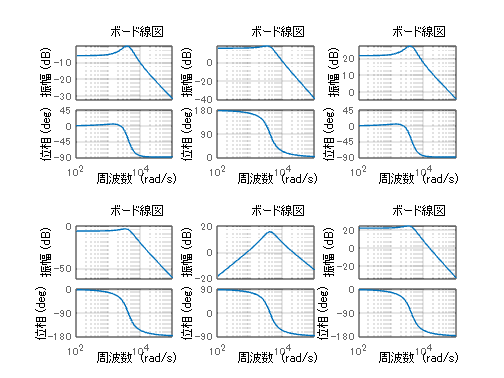

%パラメータの定義
Ro = 1;
C1 = 300e-6;
L1 = 200e-6;
Vin = 12;
Duty = 0.5;

%Symbolic式を伝達関数モデルに変換
Gplant_s = arrayfun(@sym2tf_ykamatan,subs(Gplant),'UniformOutput',false);

%モデルのサイズを取得
[row, colm] = size(Gplant);

%ループを回して各要素のボード線図を描画
for i = 1:row
    for j = 1:colm
        ax = subplot(2,3,(i-1)*colm+j);
        bodeplot(ax,Gplant_s{i,j});
        grid on;
    end
end

## 7.導出した代数式モデルをファイルに保存

%プロジェクトファイル情報を取得
proj = matlab.project.rootProject;
%ルートフォルダを起点に保存先を指定し、変数を保存
save( proj.RootFolder + "/Parameters/SymbolicEquation.mat",'Gplant', 'GdXdvin', 'GdXdRo', 'GdXdDuty');

## Reference

[1] 阿部　征哉, 財津　俊行, 上松 武.　デジタル電源の基礎と設計法 -スイッチング電源のデジタル制御-. 科学情報出版株式会社, 2020,246p, ISBN978-4-904774-84-7.

[2] Frede Blaabjerg, ed. Yanfelng Shen, Zian Qi and Huai Wang. Control of Power Electronic Converters And Systems. Volume 1, Chapter 3 "Modeling and Control of DC-DC Converters" p69-p92, Academic Press, 2018, ISBN 978-0-12-804254-7.

[3]MathWorks."Symbolic Math Toolbox 入門". MathWorks ヘルプセンター　ヘルプドキュメント,2022/10/19. [https://jp.mathworks.com/help/symbolic/getting-started-with-symbolic-math-toolbox.html](https://jp.mathworks.com/help/symbolic/getting-started-with-symbolic-math-toolbox.html)

[4]MathWorks."Control System Toolbox". MathWorks ヘルプセンター　ヘルプドキュメント,2022/10/19. [https://jp.mathworks.com/help/control/](https://jp.mathworks.com/help/control/)